clc;
clear;
Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

I=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];
Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;
t=1:length(I);

t_plus=0.363;
Rg=8.314;
T=298.15;
Rohm=1.2e-3;

% sp_soc_surfp=soc_ave_p+spe_dcsp/csmaxpos;

soc_ave_p=soc0p+cumsum(-I)/3600/Qp;
soc_ave_n=soc0n+cumsum(I)/3600/Qn;

# FOMe

tic
[fom_cen,fom_cep]=sp_electrolyte(I);
fom_cen=fom_cen';
fom_cep=fom_cep';

fom_e=(1+t_plus)*2*Rg*T/F*log(fom_cep./fom_cen);

fome_dcsen=fomn(Rsn,Dsn,Jn);
fome_dcsep=fomp(Rsp,Dsp,Jp);

fome_surfp=soc_ave_p+fome_dcsep/csmaxpos;
fome_surfn=soc_ave_n+fome_dcsen/csmaxneg;

V_fome=Eeqp(fome_surfp)-Eeqn(fome_surfn)+Rohm*I+fom_e;
toc

历时 0.433291 秒。


# FOM

tic
fom_dcsen=fom(Rsn,Dsn,Jn);
fom_dcsep=fom(Rsp,Dsp,Jp);

fom_surfp=soc_ave_p+fom_dcsep/csmaxpos;
fom_surfn=soc_ave_n+fom_dcsen/csmaxneg;

V_fom=Eeqp(fom_surfp)-Eeqn(fom_surfn)+Rohm*I;
toc

历时 0.373723 秒。


电压对比

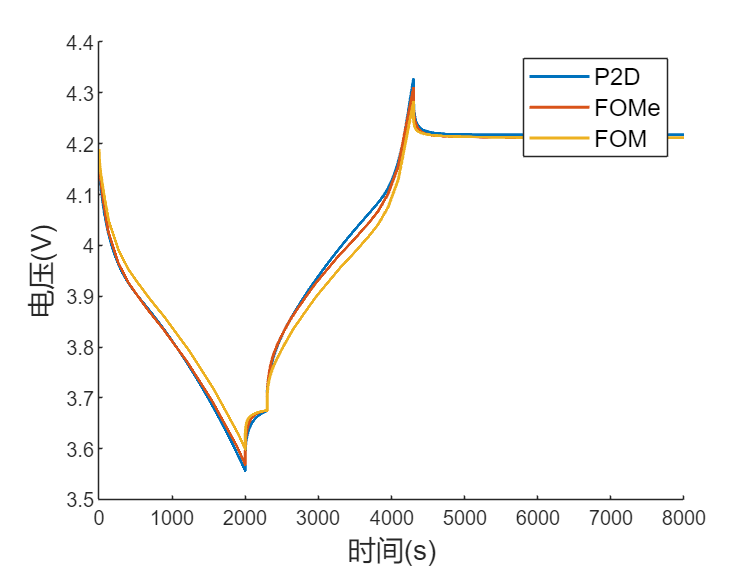

load v_cc.txt;
V_p2d=v_cc(:,2);
figure(1);
clf;
hold on;
plot(V_p2d,LineWidth=1.5);
plot(V_fome,LineWidth=1.5);
plot(V_fom,LineWidth=1.5);
legend('P2D','FOMe','FOM',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

error(1,1)=RMSE(V_p2d,V_fome)*1000;
error(1,2)=RMSE(V_p2d,V_fom)*1000;
error(2,1)=MAPE(V_p2d,V_fome);
error(2,2)=MAPE(V_p2d,V_fom);